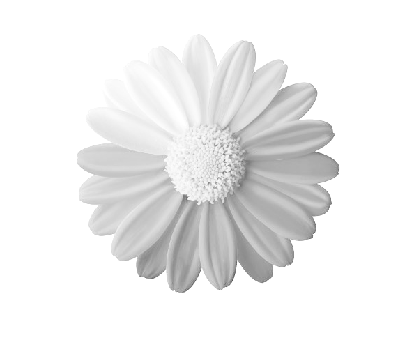

clc
clear all
close all
im=imread('flower.jpg');
im=im2double(im);
[s,p,l]=size(im);
g=im2double(0.333.*im(:,:,1)+0.666*im(:,:,2)+0.11*im(:,:,3));

gamma=0.35;
c=g.^gamma;
imshow(c)

%summ of all frequency =  number of pixels
%Plot hist 
cdg=histeq(c)

cdg =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

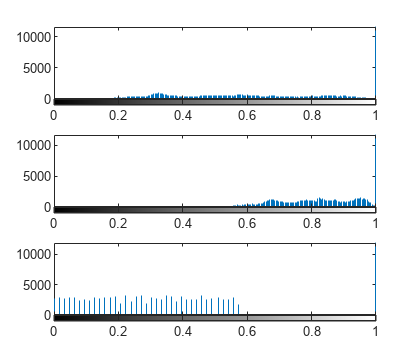

subplot(3,1,1);imhist(g);
subplot(3,1,2);imhist(c);
subplot(3,1,3);imhist(cdg)

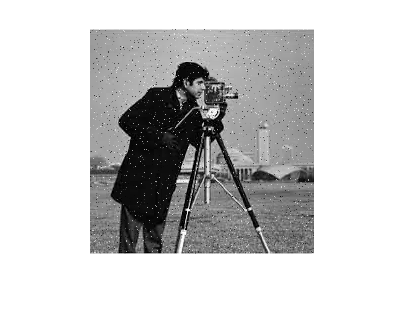

im1=imread('cameraman.jpeg');
im1=im2double(im1);
cf=rgb2gray(imnoise(im1,'salt & pepper',0.02));
figure
imshow(cf)

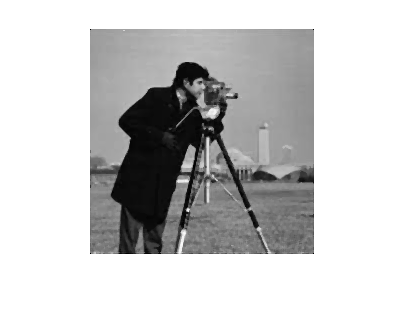

%Choose median value own code (medfilt2)
D=medfilt2(cf);
figure
imshow(D)

t=0:0.1:10

t =                    0   0.100000000000000   0.200000000000000   0.300000000000000   0.400000000000000   0.500000000000000   0.600000000000000   0.700000000000000   0.800000000000000   0.900000000000000   1.000000000000000   1.100000000000000   1.200000000000000   1.300000000000000   1.400000000000000   1.500000000000000   1.600000000000000   1.700000000000000   1.800000000000000   1.900000000000000   2.000000000000000   2.100000000000000   2.200000000000000   2.300000000000000   2.400000000000000   2.500000000000000   2.600000000000000   2.700000000000000   2.800000000000000   2.900000000000000   3.000000000000000   3.100000000000000   3.200000000000000   3.300000000000000   3.400000000000000   3.500000000000000   3.600000000000000   3.700000000000000   3.800000000000000   3.900000000000000   4.000000000000000   4.100000000000001   4.200000000000000   4.300000000000000   4.400000000000000   4.500000000000000   4.600000000000001   4.700000000000000   4.800000000000001   4.90000000000

y1=sin(20*t)

y1 =                    0   0.909297426825682  -0.756802495307928  -0.279415498198925   0.989358246623382  -0.544021110889370  -0.536572918000433   0.990607355694871  -0.287903316665065  -0.750987246771676   0.912945250727628  -0.008851309290404  -0.905578362006622   0.762558450479603   0.270905788307866  -0.988031624092862   0.551426681241691   0.529082686120024  -0.991778853443116   0.296368578709385   0.745113160479349  -0.916521547915634   0.017701925105414   0.901788347648806  -0.768254661323671  -0.262374853703929   0.986627592040485  -0.558789048851616  -0.521551002086906   0.992872648084538  -0.304810621102217  -0.739180696649223   0.920026038196791  -0.026551154023967  -0.897927680689291   0.773890681557889   0.253823362762036  -0.985146260468247   0.566107636898180   0.513978455987535  -0.993888653923375   0.313228782433099   0.733190320073292  -0.923458447004060   0.035398302733661   0.893996663600558  -0.779466069615814  -0.245251985467654   0.983587745434342  -0.5733818719

y2=sin(200*t)

y2 =                    0   0.912945250727628   0.745113160479349  -0.304810621102223  -0.993888653923375  -0.506365641109759   0.580611184212326   0.980239659440312   0.219425258379005  -0.801152635733830  -0.873297297213995   0.088398712487560   0.945445154921126   0.683239703815851  -0.387809420829229  -0.999755839901149  -0.428155428084452   0.650310740162596   0.958915723414307   0.132321870869828  -0.850919359639177  -0.826811724306801   0.176105293266022   0.970542546651270   0.616016713764119  -0.467771805322476  -0.997795279312501  -0.346592904376553   0.714918585256750   0.930083804977087   0.044182448331873  -0.894023675754660  -0.773852498155771   0.262433029780957   0.988040921917685   0.543970523363376  -0.544071696437995  -0.988022322676830  -0.262316676673239   0.773928862147197   0.893969648197021  -0.044302907677572  -0.930128092015713  -0.714834271403198   0.346706005357637   0.997803274421970   0.467665229662912  -0.616111692103339  -0.970513488904722  -0.1759865990

y3=y1(1:length(y1)-1)+y2(2:length(y2))/2

y3 =    0.456472625363814   1.281854007065356  -0.909207805859040  -0.776359825160613   0.736175426068502  -0.253715518783207  -0.046453088280278   1.100319984884373  -0.688479634531981  -1.187635895378673   0.957144606971408   0.463871268170159  -0.563958510098697   0.568653740064988  -0.228972131642709  -1.202109338135088   0.876582051322988   1.008540547827177  -0.925617918008202  -0.129091101110203   0.331707298325948  -0.828468901282623   0.502973198431048   1.209796704530866  -1.002140563984909  -0.761272493360179   0.813331139852209  -0.201329756223242  -0.056509099598362   1.014963872250475  -0.751822458979546  -1.126106945727108   1.051242553087269   0.467469306934876  -0.625942419007604   0.501854833338891  -0.240187798576379  -1.116304598804867   0.953072067971779   0.960963280086046  -1.016040107762161  -0.151835263574758   0.375773184371693  -0.750105444325241   0.534299939944646   1.127829278432014  -1.087521915667483  -0.730508729920015   0.895594445916109  -0.1599421017

x=fft(y3)

x =   1.361070694590075 + 0.000000000000000i  1.363115213826674 + 0.042507383354228i  1.369317967026036 + 0.085476619647966i  1.379892724714509 + 0.129394177179589i  1.395217458769885 + 0.174798845394498i  1.415870943882275 + 0.222316327791212i  1.442693394512321 + 0.272706189467869i  1.476884049245851 + 0.326929919517445i  1.520159241997052 + 0.386255229035775i  1.575015161800475 + 0.452424342023669i  1.645182361271619 + 0.527940436336119i  1.736454547941649 + 0.616585328397860i  1.858305701018973 + 0.724424476786300i  2.027333295903311 + 0.861940612498242i  2.275491435135328 + 1.049126751524044i  2.673240381891336 + 1.329792512452980i  3.412808820808370 + 1.822993482150231i  5.272791262133765 + 3.009938617924452i 19.077915758031253 +11.575374776332232i -7.086231667515722 - 4.536879817954577i -2.266464749417600 - 1.512722506149004i -1.010309239457738 - 0.683850233132191i -0.414974694694996 - 0.256120524924824i -0.051379573610865 + 0.037850973164375i  0.210580637584571 + 0.282051449564

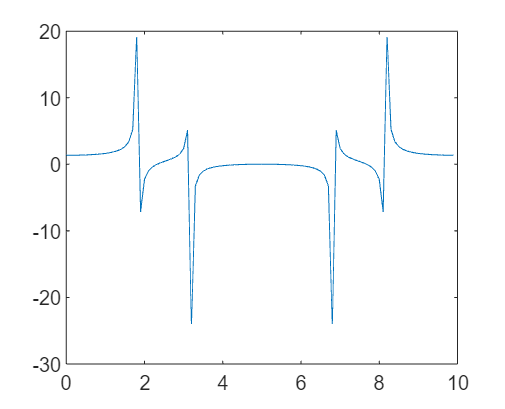

plot(t(1:length(t)-1),x)